# Battery testing, modelling, and state estimation - Online Parameter Identification and Other Functionalities

*Vaclav Knap*

Your tasks in this exercise are:

1) Build a RLS parameter estimator for 1RC ECM.

2) Build EKF parameter estimator for 1 RC ECM.

3) Plot the measurement, all the estimated parameters and provide a discussion about the results.

Hint: To solve this exercise use Lecture 8.

% This script changes all interpreters from tex to latex. 
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end
export_figures = true;
% Loading DDP measurement
ddp_meas = load_data();

T = 1;
N = length(ddp_meas.Time); % number of samples

## Initialization for the RLS parameter estimation for 1 RC

Plast = diag([1 1 1 1]); %You can tune the covariance matrix
a1 = 0.5;               %You can tune the initial parameters
b0 = -0.001;            %You can tune the initial parameters
b1 = 0.001;             %You can tune the initial parameters
lambda = 0.97;

%This is initial parameter vector
%theta = [(1+a1)*ddp_meas.Voltage(1) -a1 b0 b1]';   

init_OCV = ddp_meas.Voltage(1);
init_R0 = 80e-3;
init_R1 = 40e-3;
init_C1 = 1500;

% The simulation run for the 1RC RLS parameter estimation. It does not need
% to be changed.
rls_est_param = zeros(N, 4);
V_est_rls = zeros(N, 1);
% Initial estimates of battery parameters
rls_est_param(1, :) = [init_OCV, init_R0, init_R1, init_C1];
V_est_rls(1) = ddp_meas.Voltage(1);
% Convert them to initialization values for RLS theta
theta = battery_params_to_RLS_theta(rls_est_param(1, :), T)';

for t=2:N
[rls_est_param(t,:), Plast, theta, V_est_rls(t)] = RLS_1RC_paramest(ddp_meas.Voltage(t), ddp_meas.Voltage(t-1), -ddp_meas.Current(t), -ddp_meas.Current(t-1), T, Plast, theta, lambda);
end

OCV_RLS = rls_est_param(:, 1);
R0_RLS = rls_est_param(:, 2);
R1_RLS = rls_est_param(:, 3);
C1_RLS = rls_est_param(:, 4);

## Initialization for the Hongwen EKF parameter estimation for 1 RC

% state vector x=[OCV Vmeas V1 1/C1 1/R1 R0]'
Q_diag = [1e-4 1e-3 1e-8 1e-10 1 0.0001];
Q = diag(Q_diag);
xest = [init_OCV; init_OCV; 0; 1/init_C1; 1/init_R1; init_R0];  %You can change initial states/parameters
lastP = diag([0.5 0.5 0.25 0.03 0.01 0.001]);   %You can tune this covariance matrix
R = 0.01;    %You can tune this covariance


%The simulation run for the 1RC EKF parameter estimation. It does not need
%to be changed
ekf_est_param = zeros(N,6);

for t=1:N
[ekf_est_param(t,:), lastP] = EKF_paramest(ddp_meas.Voltage(t), -ddp_meas.Current(t), ddp_meas.Current_dot(t), T, xest, lastP, Q, R);
xest = ekf_est_param(t,:)';
end

OCV_EKF = ekf_est_param(:, 1);
V_est_EKF = ekf_est_param(:, 2);
V1_EKF = ekf_est_param(:, 3);
C1_EKF = 1 ./ ekf_est_param(:, 4);
R1_EKF = 1 ./ ekf_est_param(:, 5);
R0_EKF = ekf_est_param(:, 6);


## Initialization for the Michal EKF parameter estimation for 1 RC

% state vector x=[OCV V1 1/C1 1/R1 R0]'
Q = diag(Q_diag([1 3:6]));
xest = [init_OCV; 0; 1/init_C1; 1/init_R1; init_R0];
lastP = diag([0.5 0.25 0.03 0.01 0.001]);
R = 1e-4;    %You can tune this covariance


%The simulation run for the 1RC EKF parameter estimation. It does not need
%to be changed
ekf_vomi_est_param = zeros(N,5);
V_est_EKF_vomi = zeros(size(V_est_EKF));

for t=1:N
[ekf_vomi_est_param(t,:), lastP, V_est_EKF_vomi(t)] = EKF_paramest_vomi(ddp_meas.Voltage(t), -ddp_meas.Current(t), T, xest, lastP, Q, R);
xest = ekf_vomi_est_param(t,:)';
end

OCV_EKF_vomi = ekf_vomi_est_param(:, 1);
V1_EKF_vomi = ekf_vomi_est_param(:, 2);
C1_EKF_vomi = 1 ./ ekf_vomi_est_param(:, 3);
R1_EKF_vomi = 1 ./ ekf_vomi_est_param(:, 4);
R0_EKF_vomi = ekf_vomi_est_param(:, 5);

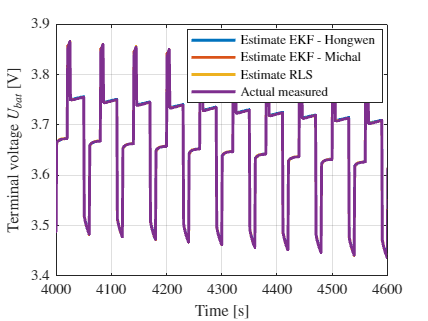

plot(ddp_meas.Time, [V_est_EKF, V_est_EKF_vomi, V_est_rls, ddp_meas.Voltage], linewidth=2);
xlabel('Time [s]');
ylabel('Terminal voltage $U_{bat}$ [V]')
grid on;
legend('Estimate EKF - Hongwen', 'Estimate EKF - Michal', 'Estimate RLS','Actual measured', location='best')
xlim([4000 4600])
if export_figures
    exportgraphics(gcf, "figures/voltages.eps");
end

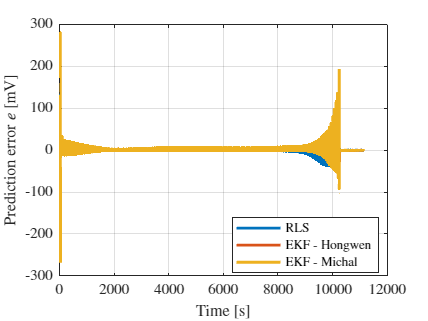


plot(ddp_meas.Time, 1000 * ([V_est_rls V_est_EKF, V_est_EKF_vomi] - ddp_meas.Voltage), linewidth=2);
xlabel('Time [s]');
ylabel('Prediction error $e$ [mV]')
grid on;
legend('RLS', 'EKF - Hongwen', 'EKF - Michal', location='best')
%ylim([2.4 4.5])
a1 = gca;
fig = figure;
a2 = copyobj(a1, fig);

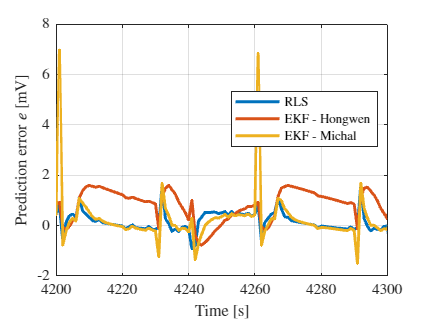

xlim([4200 4300])
legend('RLS', 'EKF - Hongwen', 'EKF - Michal', location='best')
if export_figures
    exportgraphics(fig, "figures/voltages-pred-error.eps");
end

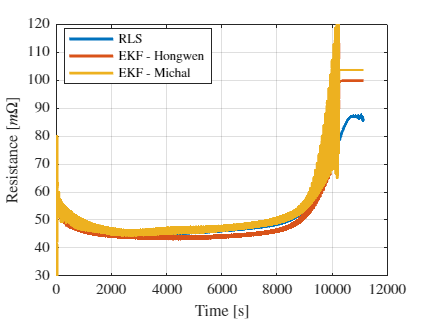


plot(ddp_meas.Time, 1000 * [R0_RLS R0_EKF R0_EKF_vomi ], linewidth=2);
xlabel('Time [s]');
ylabel('Resistance $[m\Omega]$')
grid on;
ylim([30 120])
legend('RLS', 'EKF - Hongwen', 'EKF - Michal', location='best')
if export_figures
    exportgraphics(gcf, "figures/est-R0.eps");
end

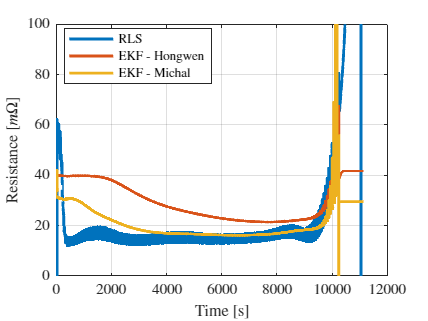

plot(ddp_meas.Time, 1000 * [R1_RLS R1_EKF R1_EKF_vomi ], linewidth=2);
xlabel('Time [s]');
ylabel('Resistance $[m\Omega]$')
grid on;
ylim([0 100])
legend('RLS', 'EKF - Hongwen', 'EKF - Michal', location='best')
if export_figures
    exportgraphics(gcf, "figures/est-R1.eps");
end

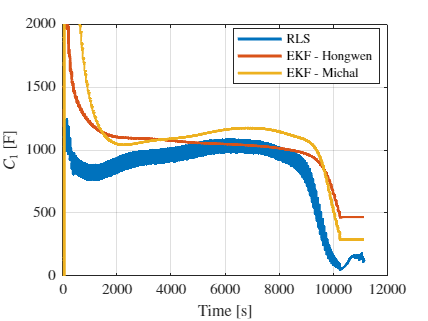

plot(ddp_meas.Time, [C1_RLS C1_EKF C1_EKF_vomi ], linewidth=2);
xlabel('Time [s]');
ylabel('$C_1$ [F]')
grid on;
legend('RLS', 'EKF - Hongwen', 'EKF - Michal', location='best')
ylim([0 2e3]);
if export_figures
    exportgraphics(gcf, "figures/est-C.eps");
end

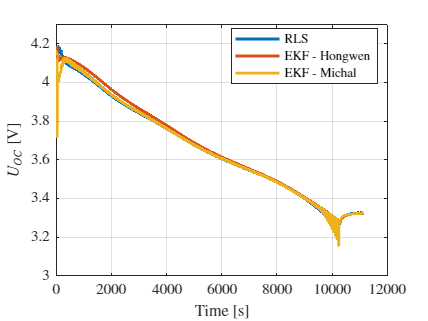


plot(ddp_meas.Time, [OCV_RLS OCV_EKF OCV_EKF_vomi ], linewidth=2);
xlabel('Time [s]');
ylabel('$U_{OC}$ [V]')
grid on;
ylim([3 4.3])
legend('RLS', 'EKF - Hongwen', 'EKF - Michal', location='best')

if export_figures
    exportgraphics(gcf, "figures/est-OCV.eps");
end

## Derivation of RLS: Express parameters OCV, R0, R1, C1 as functions of theta

syms s d R0 R1 C1 i Ubat OCV T
U1 = i * R1 / (1 + s * R1 * C1)

$$U1 = \frac{R_{1}\,i}{C_{1}\,R_{1}\,s+1}$$

eqn = Ubat == OCV - i*R0 - U1

$$eqn = \mathrm{Ubat}=\mathrm{OCV}-R_{0}\,i-\frac{R_{1}\,i}{C_{1}\,R_{1}\,s+1}$$



% E = Ubat - OCV; % Difference between OCV and terminal voltage

Gs = -(R0 + R1 / (1 + R1*C1*s)) % tf from I to E

$$Gs = -R_{0}-\frac{R_{1}}{C_{1}\,R_{1}\,s+1}$$

% Bilinear discretization
Gz = subs(Gs, s, 2/T*(1-d)/(1+d))

$$Gz = \frac{R_{1}}{\frac{2\,C_{1}\,R_{1}\,\left(d-1\right)}{T\,\left(d+1\right)}-1}-R_{0}$$

s == 2/T*(1-d)/(1+d)

$$ans = s=-\frac{2\,\left(d-1\right)}{T\,\left(d+1\right)}$$

The discrete-time transfer function from the flowing current to the voltage drop $E = U_{bat} - U_{oc}$ is then

Gz = collect(Gz, d)

$$Gz = \frac{\left(R_{0}\,T+R_{1}\,T-2\,C_{1}\,R_{0}\,R_{1}\right)\,d+R_{0}\,T+R_{1}\,T+2\,C_{1}\,R_{0}\,R_{1}}{\left(2\,C_{1}\,R_{1}-T\right)\,d-T-2\,C_{1}\,R_{1}}$$

Decompose it into numerator and denominator

[num, den] = numden(Gz);
num = coeffs(num, 'd', 'All');
den = coeffs(den, 'd', 'All');

In general, we want the transfer in the format

$G(d) = \frac{Y(d)}{U(d)} = \frac{b_0 + b_1 d}{1 + a_1 d}$,

where $a_0 = 1$ (that is the coefficient of y(k) when the TF would be rewritten as a difference equation).

% num and den are ordered by descending powers of variable d. normalize
% coefficients to have a0 = 1
syms offset a1 b0 b1
eqns = [   
offset == (1 + a1) * OCV;
a1 == den(1) / den(2);
b1 == num(1) / den(2);
b0 == num(2) / den(2);
]

$$eqns = \left(\begin{array}{c} \mathrm{offset}=\mathrm{OCV}\,\left(a_{1}+1\right)\\ a_{1}=\frac{T-2\,C_{1}\,R_{1}}{T+2\,C_{1}\,R_{1}}\\ b_{1}=-\frac{R_{0}\,T+R_{1}\,T-2\,C_{1}\,R_{0}\,R_{1}}{T+2\,C_{1}\,R_{1}}\\ b_{0}=-\frac{R_{0}\,T+R_{1}\,T+2\,C_{1}\,R_{0}\,R_{1}}{T+2\,C_{1}\,R_{1}} \end{array}\right)$$

% Declare symbolic variables for parameters
sol = solve(eqns, [OCV R0 R1 C1])

sol = struct with fields:
    OCV: offset/(a1 + 1)
     R0: (b0 - b1)/(a1 - 1)
     R1: (2*(b1 - a1*b0))/(a1^2 - 1)
     C1: -(T*a1^2 - 2*T*a1 + T)/(4*(b1 - a1*b0))



% The following substitution is not really needed, but it is done in the
% derivation in the lectures... Perform it to check results
%syms a2 a3
%sol = subs(sol, {a1 b0 b1}, {-a1 a2 a3}); 
% Check the results
sol.R0

$$ans = \frac{b_{0}-b_{1}}{a_{1}-1}$$

sol.R1

$$ans = \frac{2\,\left(b_{1}-a_{1}\,b_{0}\right)}{{a_{1}}^{2}-1}$$

sol.C1

$$ans = -\frac{T\,{a_{1}}^{2}-2\,T\,a_{1}+T}{4\,\left(b_{1}-a_{1}\,b_{0}\right)}$$

[sol.R0; sol.R1; sol.C1]

$$ans = \left(\begin{array}{c} \frac{b_{0}-b_{1}}{a_{1}-1}\\ \frac{2\,\left(b_{1}-a_{1}\,b_{0}\right)}{{a_{1}}^{2}-1}\\ -\frac{T\,{a_{1}}^{2}-2\,T\,a_{1}+T}{4\,\left(b_{1}-a_{1}\,b_{0}\right)} \end{array}\right)$$

function [xest, lastP]   = EKF_paramest(voltage, current, derivcur, Ts, xest, lastP, Q, R)
%Use Lecture 8, slide 16 to build this EKF.
%You can also use the source: H. Hongwen, et al., “Online estimation of model parameters and state-of-charge of LiFePO4 batteries in electric vehicles”, 2011.

x = xest;   %the states marked as x
u = current;
u_dot = derivcur;
%Kalman Prediction Step
%State Estimate
f1 = 0;      %fill state function for state 1
f2 = x(1)*x(4)*x(5) - x(2)*x(4)*x(5) - (x(4)*x(5)*x(6) + x(4)) * u - x(6) * u_dot;      %fill state function for state 2
f3 = x(4)*u - x(3)*x(4)*x(5);      %fill state function for state 3
f4 = 0;      %fill state function for state 4
f5 = 0;      %fill state function for state 5
f6 = 0;      %fill state function for state 6
dx = [f1;f2;f3;f4;f5;f6];
xPre = x + dx*Ts;

%Liniarized A Matrix for the covariance prediction Step 
A = zeros(6,6);
A(2,1) = x(4)*x(5);     %fill the corresponding element to the matrix A
A(2,2) = -x(4)*x(5);     %fill the corresponding element to the matrix A
A(2,4) = x(1)*x(5) - x(2)*x(5) - (x(5)*x(6) + 1)*u;     %fill the corresponding element to the matrix A    
A(2,5) = x(1)*x(4) - x(2)*x(4) - x(4)*x(6)*u;     %fill the corresponding element to the matrix A
A(2,6) = -x(4)*x(5)*u - u_dot;     %fill the corresponding element to the matrix A

A(3,3) = -x(4)*x(5);     %fill the corresponding element to the matrix A    
A(3,4) = u - x(3)*x(5);     %fill the corresponding element to the matrix A
A(3,5) = -x(3)*x(4);     %fill the corresponding element to the matrix A

%discretization of A
A_hat = eye(6) + A * Ts;
% Covariance Prediction
PPre = A_hat * lastP * A_hat' + Q ;


%Correction Step
C = [0 1 0 0 0 0];

%Compute the Kalman Gain:
CT = transpose(C);
S = C*PPre*CT + R;
kalmanGain = (PPre*CT) / S;

zPre = xPre(2);
resid = voltage - zPre  ;

xest = xPre + kalmanGain*resid;
Id = eye(size(PPre));

Pest = (Id-kalmanGain*C) * PPre * (Id-kalmanGain*C)' + kalmanGain * R * kalmanGain';
lastP = Pest;
end

function [xest, lastP, yest] = EKF_paramest_vomi(voltage, current, Ts, xest, lastP, Q, R)
% state vector x=[OCV V1 1/C1 1/R1 R0]'
%Use Lecture 8, notes after slide 16 to build this EKF.

x = xest;   %the states marked as x
u = current;
%Kalman Prediction Step
%State Estimate
f1 = 0;      
f2 = -x(2)*x(3)*x(4) + x(3)*u;
f3 = 0;      
f4 = 0;      
f5 = 0;      
dx = [f1;f2;f3;f4;f5];
x_hat = x + dx*Ts;

%Liniarized A Matrix for the covariance prediction Step 
A = zeros(5,5);

A(2, :) = [0 -x(3)*x(4) u-x(2)*x(4) -x(2)*x(3) 0];

%discretization of A
A_hat = eye(5) + A * Ts;
% Covariance Prediction
PPre = A_hat * lastP * A_hat' + Q ;


%Correction Step
C = [1 -1 0 0 -u];

%Compute the Kalman Gain:
CT = transpose(C);
S = C*PPre*CT + R;
kalmanGain = (PPre*CT) / S;

yest = x(1) - x(2) - u*x(5);
resid = voltage - yest;

xest = x_hat + kalmanGain*resid;
Id = eye(size(PPre));

Pest = (Id-kalmanGain*C) * PPre * (Id-kalmanGain*C)' + kalmanGain * R * kalmanGain';
lastP = Pest;
end


function [est_param, Plast, theta, V_est] = RLS_1RC_paramest(V_now, V_prev, I_now, I_prev, Ts, Plast, theta, lambda)
%RLS model parameter estimator
%Use Lecture 8, slides 6, 8, and 11 to build the RLS estimator
% You can also use: "Online model-based estimation of state-of-charge and open-circuit voltage
%of lithium-ion batteries in electric vehicles" doi:10.1016/j.energy.2012.01.009

phi = [1; -V_prev; I_now; I_prev];
V_est = phi' * theta;
error = V_now - V_est;

K = Plast *  phi / (lambda + phi' * Plast * phi);

theta = theta + K * error;

Plast = 1/lambda * (Plast - K * phi' * Plast);

% at some point, you will arrive to parameters a1, a2, a3, and OCV. You
% will need to extract from them R0, R1, and C1. You can use symbolic
% computation "syms" and equation solver "solve" for those parameters [R0
% R1 C1]
est_param = RLS_theta_to_battery_params(theta, Ts);
end

function params = RLS_theta_to_battery_params(theta, Ts)
offset = theta(1);
a1 = theta(2);
b0 = theta(3);
b1 = theta(4);

% OCV, R0, R1, C1
OCV = offset / (1 + a1);
R0 = (b0 - b1) / (a1 - 1);
R1 = 2 * (b1 - a1 * b0) / (a1^2 - 1);
C1 = - Ts * (1 - a1)^2 / 4 / (b1 - a1 * b0);
params = [OCV R0 R1 C1];
end

function theta = battery_params_to_RLS_theta(params, Ts)
OCV = params(1);
R0 = params(2);
R1 = params(3);
C1 = params(4);

% OCV, R0, R1, C1
a1 = (Ts - 2 * C1 * R1) / (Ts + 2 * C1 * R1);
b1 = -(R0 * Ts + R1 * Ts - 2 * C1 * R0 * R1) / (Ts + 2 * C1 * R1);
b0 = -(R0 * Ts + R1 * Ts + 2 * C1 * R0 * R1) / (Ts + 2 * C1 * R1);
offset = OCV * (1 + a1);

theta = [offset a1 b0 b1];
end

function result = load_data()
data = readtable('dpp\dpp.xlsx','Sheet','record');    %loading data

result.Time = seconds(duration(data.TotalTime, Inputformat="hh:mm:ss.SSS"));
[result.Time, unique_mask, ~] = unique(result.Time);

result.Voltage = data.Voltage_V__V_(unique_mask);
result.Current = data.Current_A__A_(unique_mask);

result.Current_dot = [0; diff(-result.Current)];  %generating current derivative vector
end